## displayFormula 사용법

https://kr.mathworks.com/help/symbolic/displayformula.html

syms A [3 3]
syms v B [3 1]
eqn = B == A*v

$$eqn = \left(\begin{array}{c} B_{1}=A_{1,1}\,v_{1}+A_{1,2}\,v_{2}+A_{1,3}\,v_{3}\\ B_{2}=A_{2,1}\,v_{1}+A_{2,2}\,v_{2}+A_{2,3}\,v_{3}\\ B_{3}=A_{3,1}\,v_{1}+A_{3,2}\,v_{2}+A_{3,3}\,v_{3} \end{array}\right)$$

displayFormula("B == A*v")

$$\left(\begin{array}{c} B_{1}\\ B_{2}\\ B_{3} \end{array}\right)=\left(\begin{array}{ccc} A_{1,1} & A_{1,2} & A_{1,3}\\ A_{2,1} & A_{2,2} & A_{2,3}\\ A_{3,1} & A_{3,2} & A_{3,3} \end{array}\right)\,\left(\begin{array}{c} v_{1}\\ v_{2}\\ v_{3} \end{array}\right)$$

S = "m*diff(y,t,t) == m*g-k*y"

S = "m*diff(y,t,t) == m*g-k*y"

symstr = ["'the equation of motion is'"; S;"'where k is the elastic coefficient.'"];
displayFormula(symstr)

$$\mathrm{the equation of motion is}$$

$$m\,\frac{\partial^{2}}{\partial t^{2}}y\left(x\right)=m\,g-k\,y\left(x\right)$$

$$\mathrm{where k is the elastic coefficient.}$$

syms x y
P = expand(sin(x+3*y))

$$P = 4\,\sin\left(x\right)\,{\cos\left(y\right)}^{3}+4\,\cos\left(x\right)\,\sin\left(y\right)\,{\cos\left(y\right)}^{2}-3\,\sin\left(x\right)\,\cos\left(y\right)-\cos\left(x\right)\,\sin\left(y\right)$$

C=collect(P,[sin(x) sin(y)])

$$C = \left(4\,{\cos\left(y\right)}^{3}-3\,\cos\left(y\right)\right)\,\sin\left(x\right)+\left(4\,\cos\left(x\right)\,{\cos\left(y\right)}^{2}-\cos\left(x\right)\right)\,\sin\left(y\right)$$

% 방정식에서 표현식 분리하기
syms y(t) a b c
eqn = a*y(t)^2 + b*c == 0;
isolate(eqn, y(t))

$$ans = y\left(t\right)=\frac{\sqrt{-b}\,\sqrt{c}}{\sqrt{a}}$$

syms id(t)
y = id(t)^2*diff(id(t),t);
Dy = diff(y,id(t))

$$Dy = 2\,\text{id}\left(t\right)\,\frac{\partial }{\partial t}\text{id}\left(t\right)$$

syms y(x)
f = y*sin(y);
G = functionalDerivative(f,y)

$$G(x) = \sin\left(y\left(x\right)\right)+\cos\left(y\left(x\right)\right)\,y\left(x\right)$$

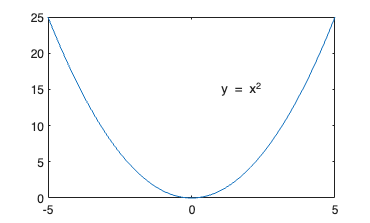

syms x
y = x^2;
fplot(y)
ylabel = texlabel(y);
text(1, 15, ['y = ' ylabel]);